# RANSAC- RANdomSample Consensus

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-12-10

### Step-by-Step Guideline

rng(40); %fixed random number order

num_pt = 100;

% line equation y = mx + b;
m = 2;
b = 4;

% x-axis range
xrange = [-10 10];
x = rand(num_pt,1)*(xrange(2)-xrange(1))+xrange(1);

y_true = m*x+b;
x_meas = x; 
y_meas = y_true + (rand([num_pt 1])*2-1);

yrange = m*xrange+b;
x_out = rand(num_pt*0.5,1)*(xrange(2)-xrange(1))+xrange(1);
y_out = rand(num_pt*0.5,1)*(yrange(2)-yrange(1))+yrange(1);

num_pt_new = num_pt + numel(x_out);
Xmat = [[x_meas;x_out] ones(num_pt_new,1)];
Ymat = [y_meas;y_out];
fparam = pinv(Xmat)*Ymat;

x_data = [x_meas;x_out];
y_data = [y_meas;y_out];

figure(1)
plot(x_data, y_data, 'ob', 'linewidth', 1.5);hold on;
line(xrange,m*xrange + b, 'Color', 'g', 'linewidth',  2, 'LineStyle', '--');
line(xrange,fparam(1)*xrange + fparam(2), 'Color', 'r', 'linewidth',  2, 'LineStyle', '--');
legend({'data',strcat('true line:  ', 'y=',sprintf('%d',m),'x+',sprintf('%d',b)), strcat('y=',sprintf('%3.3f',fparam(1)),'x+',sprintf('%3.3f',fparam(2)))},'location','northwest','FontSize',10)
axis tight;grid on; hold off
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold')

% Step 1 ----------------------------------------------------------------------------
% rng(120); 
% rng(100); 
pt_idx = randperm(num_pt_new,2);
x_sub = x_data(pt_idx);
y_sub = y_data(pt_idx);

% https://en.wikipedia.org/wiki/Line_(geometry)
mh = diff(y_sub)/diff(x_sub);
bh = det([y_sub x_sub])/diff(x_sub);

figure(1);
plot(x_data, y_data, 'ob', 'linewidth', 1.5);hold on;
plot(x_sub, y_sub, 'or', 'linewidth', 3);hold on;
legend({'data','selected'},'location','northwest','FontSize',10)
title('Step1: Randomly Select Two Points');
axis tight;grid on; hold off
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

% Step 2 ----------------------------------------------------------------------------
figure(2);
plot(x_data, y_data, 'ob', 'linewidth', 1.5);hold on;
plot(x_sub, y_sub, 'or', 'linewidth', 3);
line(xrange,mh*xrange + bh, 'Color', 'g', 'linewidth',  2, 'LineStyle', '--');
legend({'data','selected','hyposis line'},'location','northwest','FontSize',10)
title('Step2: Generate a hyposis model');
axis tight;grid on; hold off
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

% Step 3 ----------------------------------------------------------------------------
dist_pt = mh*x_data+bh-y_data;

figure(3);
plot(x_data, y_data, 'ob', 'linewidth', 1.5);hold on;
plot(x_sub, y_sub, 'or', 'linewidth', 3);
line(xrange,mh*xrange + bh, 'Color', 'g', 'linewidth',  2, 'LineStyle', '--');

Xpt = [x_data'; x_data'];
Ypt = [y_data'; (mh*x_data+bh)'];
line(Xpt,Ypt, 'Color', 'm', 'linewidth',  1, 'LineStyle', '--');

legend({'data','selected','hyposis line','distance'},'location','northwest','FontSize',10)
title('Step3: Compute distances between the data and estimates');
axis tight;grid on; hold off
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

% Step 4 ----------------------------------------------------------------------------
dist_threshold = 2;
valid_pt = abs(dist_pt)<dist_threshold;

figure(4);
plot(x_data, y_data, 'ob', 'linewidth', 1.5);hold on;
plot(x_sub, y_sub, 'or', 'linewidth', 3);
line(xrange,mh*xrange + bh, 'Color', 'g', 'linewidth',  2, 'LineStyle', '--');
plot(x_data(valid_pt), y_data(valid_pt), 'ok', 'linewidth', 3);
plot(x_sub, y_sub, 'or', 'linewidth', 3); % redraw points
legend({'data','selected','hyposis line','valid points'},'location','northwest','FontSize',10)
title('Step4: Select inliers within a distance threshold');
axis tight;grid on; hold off
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

% Step 5 ----------------------------------------------------------------------------
figure(5);
plot(x_sub, y_sub, 'or', 'linewidth', 3); hold on
line(xrange,mh*xrange + bh, 'Color', 'g', 'linewidth',  2, 'LineStyle', '--');
plot(x_data(valid_pt), y_data(valid_pt), 'ok', 'linewidth', 3);
plot(x_sub, y_sub, 'or', 'linewidth', 3); % redraw points
legend({'selected','hyposis line','valid points'},'location','northwest','FontSize',10)
title(strcat('Step5: Count the number of inliners ', sprintf(' (%d)',sum(valid_pt))));
axis tight;grid on; hold off
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');


% % plots for slides
% rng(100); 
% pt_idx = randperm(num_pt_new,2);
% x_sub = x_data(pt_idx);
% y_sub = y_data(pt_idx);
% 
% mh = diff(y_sub)/diff(x_sub);
% bh = det([y_sub x_sub])/diff(x_sub);
% dist_pt = mh*x_data+bh-y_data;
% 
% figure(11)
% plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
% plot(x_out, y_out, 'oc', 'linewidth', 1.5);hold on;
% legend({'data','outlier'},'location','northwest','FontSize',10)
% axis tight;grid on; hold off
% xlabel('\bf X-axis');xlim(xrange);
% ylabel('\bf Y-axis');ylim(yrange);
% set(gca,'FontSize',10,'linewidth',2,'fontweight','bold')
% 
% figure(12)
% plot(x_data, y_data, 'ob', 'linewidth', 1.5);hold on;
% plot(x_sub, y_sub, 'or', 'linewidth', 3);
% line(xrange,mh*xrange + bh, 'Color', 'g', 'linewidth',  2, 'LineStyle', '--');
% 
% Xpt = [x_data'; x_data'];
% Ypt = [y_data'; (mh*x_data+bh)'];
% line(Xpt,Ypt, 'Color', 'm', 'linewidth',  1, 'LineStyle', '--');
% 
% plot(x_out, y_out, 'oc', 'linewidth', 1.5);hold on;
% 
% legend({'data','selected','hyposis line','distance'},'location','northwest','FontSize',10)
% 
% axis tight;grid on; hold off
% xlabel('\bf X-axis');xlim(xrange);
% ylabel('\bf Y-axis');ylim(yrange);
% set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');
% 
% % 
% dist_threshold = 1;
% valid_pt = abs(dist_pt)<dist_threshold;
% 
% figure(13);
% plot(x_sub, y_sub, 'or', 'linewidth', 3); hold on
% line(xrange,mh*xrange + bh, 'Color', 'g', 'linewidth',  2, 'LineStyle', '--');
% 
% vald_pt_data = valid_pt;
% vald_pt_data(1+num_pt:end)=0;
% 
% vald_pt_out = valid_pt;
% vald_pt_out(1:num_pt)=0;
% 
% plot(x_data(vald_pt_data), y_data(vald_pt_data), 'ob', 'linewidth', 1.5);
% plot(x_data(vald_pt_out), y_data(vald_pt_out), 'oc', 'linewidth', 1.5);
% 
% plot(x_sub, y_sub, 'or', 'linewidth', 3); % redraw points
% legend({'selected','hyposis line','valid points from data','valid points from outliers'},'location','northwest','FontSize',10)
% title(strcat(sprintf('Number of inliers from data and outliers: %d and %d',sum(valid_pt(1:num_pt)),sum(valid_pt(num_pt+1:end)))));
% axis tight;grid on; hold off
% xlabel('\bf X-axis');xlim(xrange);
% ylabel('\bf Y-axis');ylim(yrange);
% set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');
% 
% dist_threshold = 4;
% valid_pt = abs(dist_pt)<dist_threshold;
% 
% figure(14);
% plot(x_sub, y_sub, 'or', 'linewidth', 3); hold on
% line(xrange,mh*xrange + bh, 'Color', 'g', 'linewidth',  2, 'LineStyle', '--');
% 
% vald_pt_data = valid_pt;
% vald_pt_data(1+num_pt:end)=0;
% 
% vald_pt_out = valid_pt;
% vald_pt_out(1:num_pt)=0;
% 
% plot(x_data(vald_pt_data), y_data(vald_pt_data), 'ob', 'linewidth', 1.5);
% plot(x_data(vald_pt_out), y_data(vald_pt_out), 'oc', 'linewidth', 1.5);
% 
% plot(x_sub, y_sub, 'or', 'linewidth', 3); % redraw points
% legend({'selected','hyposis line','valid points from data','valid points from outliers'},'location','northwest','FontSize',10)
% title(strcat(sprintf('Number of inliers from data and outliers: %d and %d',sum(valid_pt(1:num_pt)),sum(valid_pt(num_pt+1:end)))));
% axis tight;grid on; hold off
% xlabel('\bf X-axis');xlim(xrange);
% ylabel('\bf Y-axis');ylim(yrange);
% set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');
% 
% dist_threshold = 10;
% valid_pt = abs(dist_pt)<dist_threshold;
% 
% figure(15);
% plot(x_sub, y_sub, 'or', 'linewidth', 3); hold on
% line(xrange,mh*xrange + bh, 'Color', 'g', 'linewidth',  2, 'LineStyle', '--');
% 
% vald_pt_data = valid_pt;
% vald_pt_data(1+num_pt:end)=0;
% 
% vald_pt_out = valid_pt;
% vald_pt_out(1:num_pt)=0;
% 
% plot(x_data(vald_pt_data), y_data(vald_pt_data), 'ob', 'linewidth', 1.5);
% plot(x_data(vald_pt_out), y_data(vald_pt_out), 'oc', 'linewidth', 1.5);
% 
% plot(x_sub, y_sub, 'or', 'linewidth', 3); % redraw points
% legend({'selected','hyposis line','valid points from data','valid points from outliers'},'location','northwest','FontSize',10)
% title(strcat(sprintf('Number of inliers from data and outliers: %d and %d',sum(valid_pt(1:num_pt)),sum(valid_pt(num_pt+1:end)))));
% axis tight;grid on; hold off
% xlabel('\bf X-axis');xlim(xrange);
% ylabel('\bf Y-axis');ylim(yrange);
% set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

### How to Decide the Number of Trials (N)

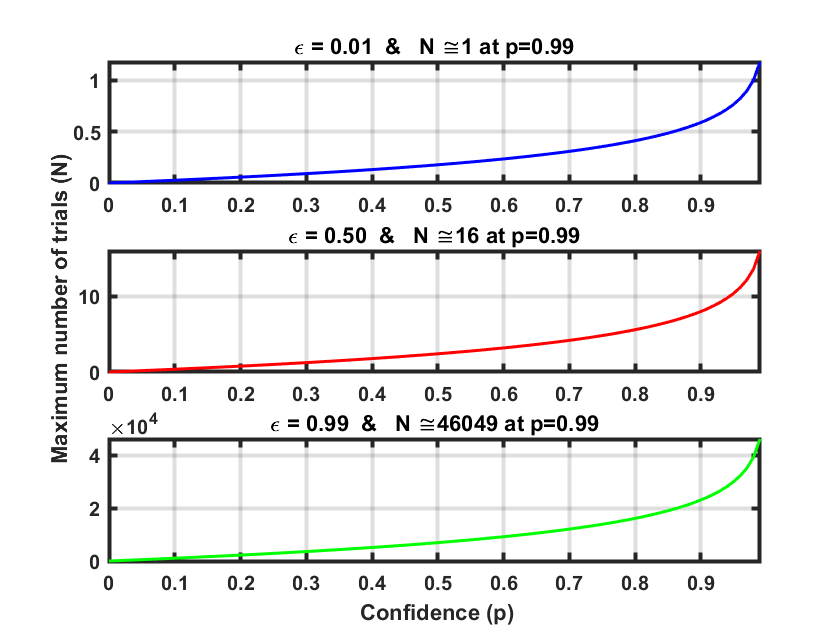

clear; clc;

p = 0:0.01:1;
err = [0.01 0.5 0.99];
n = 2;

N = zeros(numel(err),numel(p));
for ii=1:numel(err)
    N(ii,:) = log(1-p)./log(1-(1-err(ii))^n);
end

figure(1)
subplot(311);plot(p,N(1,:), 'b', 'linewidth', 1.5); 
title(strcat('\epsilon', sprintf(' = %.2f', err(1)), '  &   N \cong', sprintf('%.0f',N(1, end-1)), ' at p=0.99'));
axis tight;grid on; hold off
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

subplot(312);plot(p,N(2,:), 'r', 'linewidth', 1.5); 
title(strcat('\epsilon', sprintf(' = %.2f', err(2)), '  &   N \cong', sprintf('%.0f',N(2, end-1)), ' at p=0.99'));
axis tight;grid on; hold off
ylabel('\bf Maximum number of trials (N)');
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

subplot(313);plot(p,N(3,:), 'g', 'linewidth', 1.5); 
title(strcat('\epsilon', sprintf(' = %.2f', err(3)), '  &   N \cong', sprintf('%.0f',N(3, end-1)), ' at p=0.99'));
axis tight;grid on; hold off
xlabel('\bf Confidence (p)');
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

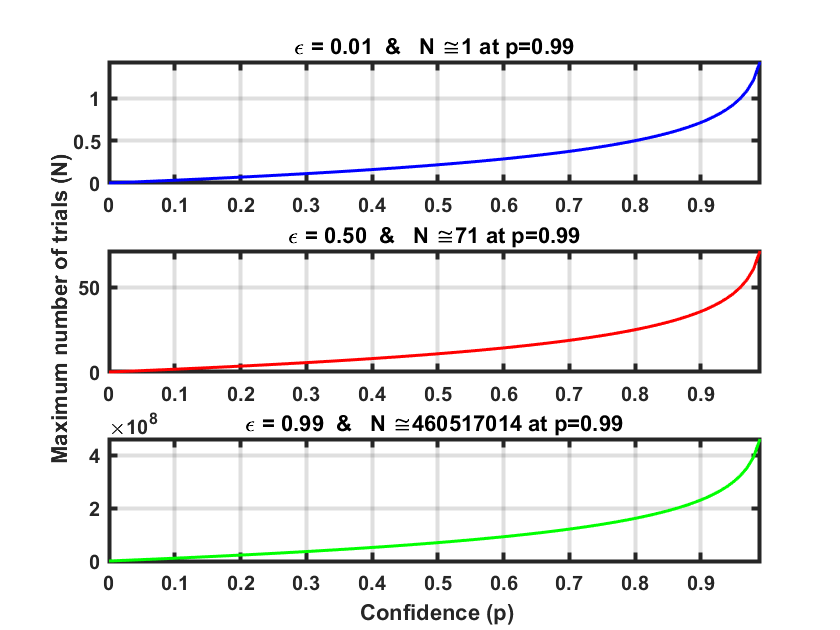


clear; clc;
p = 0:0.01:1;
err = [0.01 0.5 0.99];
n = 4;

N = zeros(numel(err),numel(p));
for ii=1:numel(err)
    N(ii,:) = log(1-p)./log(1-(1-err(ii))^n);
end

figure(2)
subplot(311);plot(p,N(1,:), 'b', 'linewidth', 1.5); 
title(strcat('\epsilon', sprintf(' = %.2f', err(1)), '  &   N \cong', sprintf('%.0f',N(1, end-1)), ' at p=0.99'));
axis tight;grid on; hold off
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

subplot(312);plot(p,N(2,:), 'r', 'linewidth', 1.5); 
title(strcat('\epsilon', sprintf(' = %.2f', err(2)), '  &   N \cong', sprintf('%.0f',N(2, end-1)), ' at p=0.99'));
axis tight;grid on; hold off
ylabel('\bf Maximum number of trials (N)');
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');

subplot(313);plot(p,N(3,:), 'g', 'linewidth', 1.5); 
title(strcat('\epsilon', sprintf(' = %.2f', err(3)), '  &   N \cong', sprintf('%.0f',N(3, end-1)), ' at p=0.99'));
axis tight;grid on; hold off
xlabel('\bf Confidence (p)');
set(gca,'FontSize',10,'linewidth',2,'fontweight','bold');